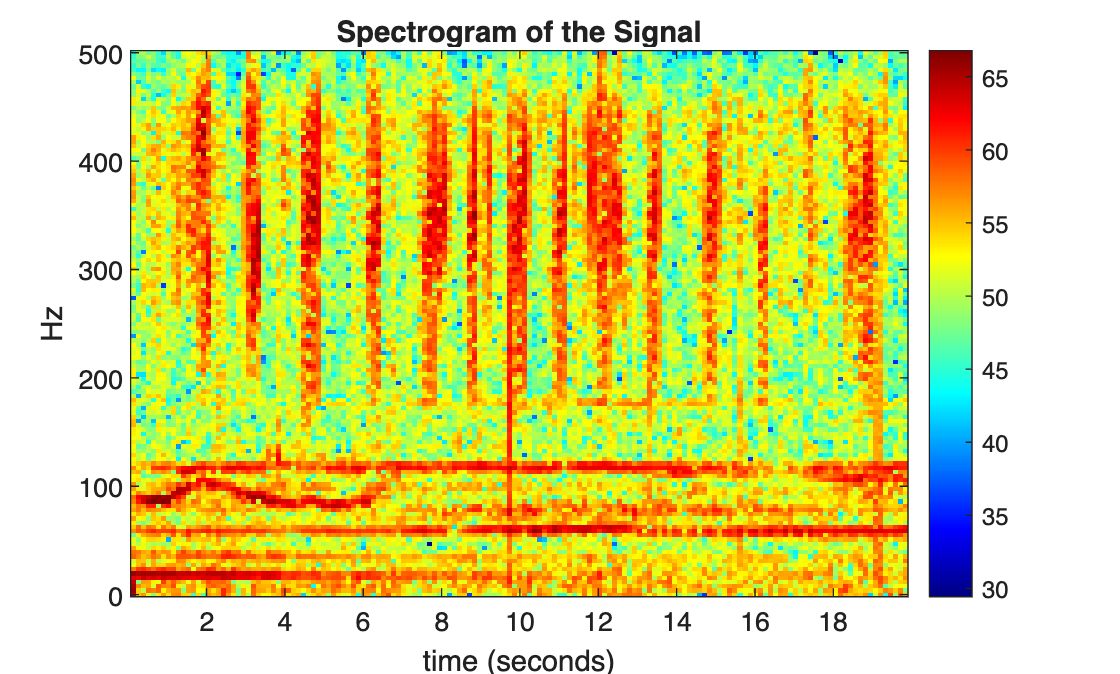

clear
close all
fname = "soundsampDA23A0T20230717T000000.gsi_20230717T075959.mat";
data = load(fname);
x = data.x; % Assuming 'data' is the variable containing the signal in the loaded .mat file
nfft = 256; % Define the number of FFT points
window = hamming(nfft); % Define the window for the spectrogram
noverlap = nfft/2; % Define the number of overlapping samples
[s,f,t] = spectrogram(x(:,1),window,noverlap,nfft,data.Fs);

Pdb = 10 * log10(abs(s)); % magnitude and convert db
imagesc(t,f,Pdb);
axis xy
xlabel("time (seconds)");
ylabel("Hz");
colorbar
colormap("jet")
soundsc(x(:,1),2 * data.Fs) % play sound aloud
title("Spectrogram of the Signal");